n1 = 1;
d1 = [1 4];
A = tf(n1, d1);

n2 = 2;
d2 = [1 0 9];
B = tf(n2, d2);

n3 = [1 1];
C = tf(n3, 1);

D = series(A,B);

Funciones

Lz_A = series(D,C)

Lz_A =
 
         2 s + 2
  ----------------------
  s^3 + 4 s^2 + 9 s + 36
 
Continuous-time transfer function.
Model Properties


Lz_C = feedback(D,C)

Lz_C =
 
             2
  -----------------------
  s^3 + 4 s^2 + 11 s + 38
 
Continuous-time transfer function.
Model Properties


Entrada Escalon y polos lazo abierto

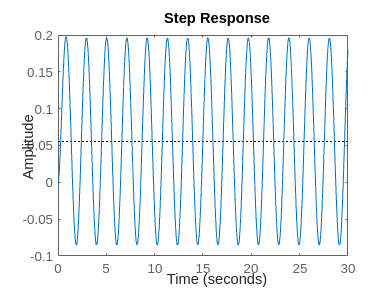

%30 para graficar, solo 30 segundos
step(Lz_A, 30)

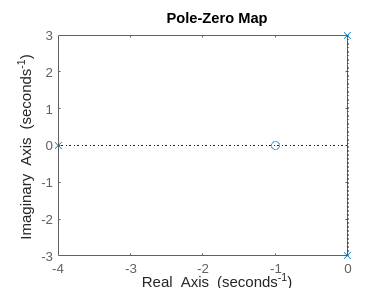

%Para solo mostrar los polos
pzmap(Lz_A)

Entrada Escalon y polos lazo cerrado

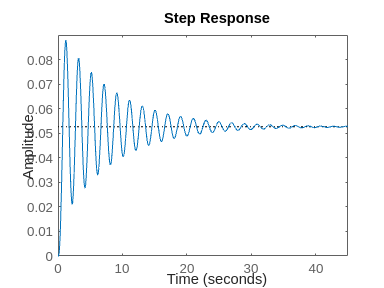

%45 para graficar, solo 45 segundos
step(Lz_C, 45)

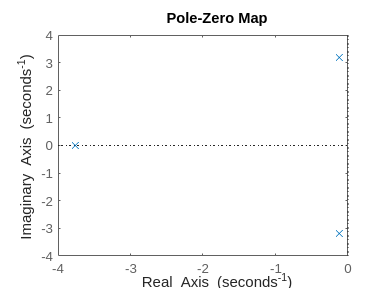

%Para solo mostrar los polos
pzmap(Lz_C)